## 说明

本脚本是使用标量衍射理论讨论SPRM的点扩散函数在不同焦面下的成像情况，本脚本假设透镜是理想透镜，能够使任意张角内的光束通过。

本脚本只考虑了单透镜成像，其实两个透镜成像是一样的。对于散射场，两个透镜成像，就是物场像经过物镜成为准直光束，然后再经由成像透镜汇聚到相机端。对于反射场，由物镜聚焦成点，再经由成像透镜准直成平行光。如果物场和像场的坐标系都进行归一化（类似于成等大颠倒的像），那么由成像透镜出射的光束与入射到物镜的光束的角度是一样的，所以实际模拟的时候只考虑了离焦对散射场成像的影响，平行光认为不受离焦的影响。理论上考虑平行光也是可以的，但是由于模拟涉及到截断，所以考虑平行光的时候会出现问题，也就没有考虑平行光了。

对于散射光，模拟的时候对其倏逝区域的频率分率分量进行了截断，这是可以接受的，因为倏逝波不能传播到远场，同时对应着透镜是理想透镜。

### 参数

clear 

d10 = 2.5/1000;   % 物面是2.5mm
d20 = 60*d10;  % 像面是60cm
f = 1/(1/d10 + 1/d20);  % 焦距
deltaz = -2e-6;  % 物面离焦距离
d1 = d10 + deltaz;  % 物面实际位置
d2 = d20;   % 像面实际位置
d0 = 1/(1/d1 + 1/d2 - 1/f); 

### 物场波函数

n = 1.55;   % 玻璃折射率
lambda = 680/10^9;
kapa = 10;  % SPP传播长度
phi = 0;    % Psi
scale_factor = .1; % 散射因子
M_size = 201;
theta_spp = 90;
theta_res = 66.7;   
[Ei,Es,~,I] = wave_generate(lambda*1e9,n,kapa,0,phi,scale_factor,M_size,theta_spp,theta_res);
U1 = Es;    % 物面散射场
F1 = fftshift(fft2(ifftshift(Es)));

### CTF

x = -100:100;
k = 1.55*2*pi/lambda;
fcut = 1*1.55*k/(2*pi);  % 空间截止频率 
[X1,Y1] = meshgrid(x,x);
fx1 = 10^7/M_size*X1;   % 物面横向频率
fy1 = 10^7/M_size*Y1;   % 物面纵向频率
X2 = lambda*d1*fx1; % 透镜面与物面相对应的空间横向坐标
Y2 = lambda*d1*fy1; % 透镜面与物面相对应的空间纵向坐标
P = sqrt(fx1.^2 + fy1.^2);  % 瞳函数
P(P<=fcut) = 1;
P(P>=fcut) = 0;
CTF0 = P.*exp(-i*k/2/d0*(X2.^2 + Y2.^2));  % 离焦瞳函数
CTF = conj(imrotate(CTF0,180));

### CTF成像平面

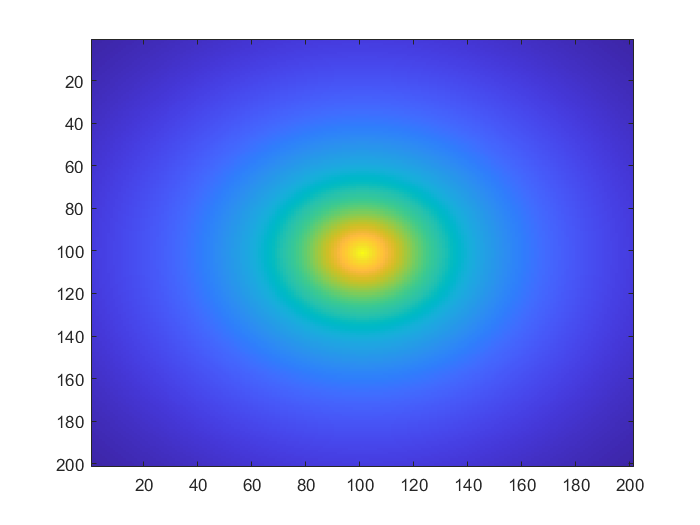

F3 = CTF.*F1;
U3 = fftshift(ifft2(ifftshift(F3)));
figure
imagesc(abs(Es).^2)

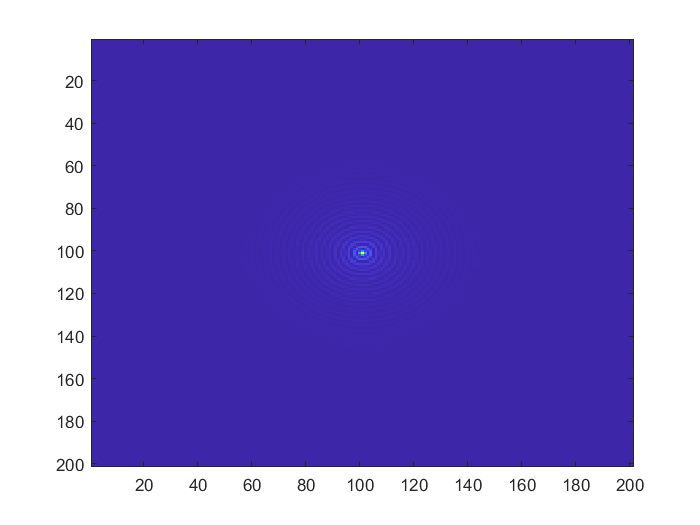

figure
imagesc(abs(U3).^2)

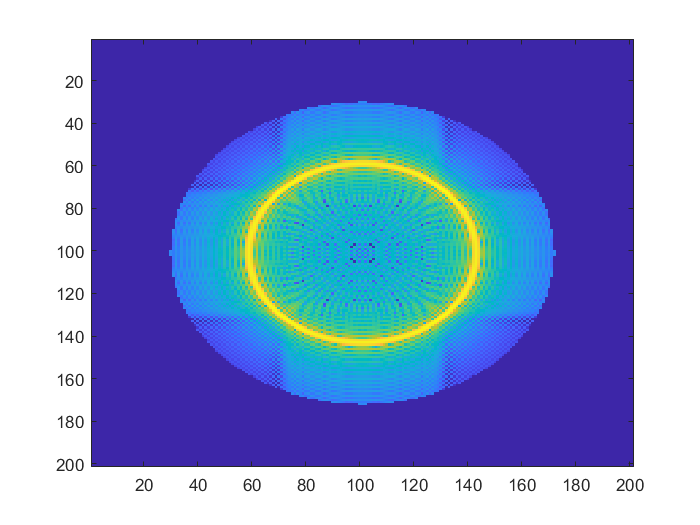

% figure
% imagesc(abs(U3+Ei).^2)
figure
imagesc(log(abs(F3)))

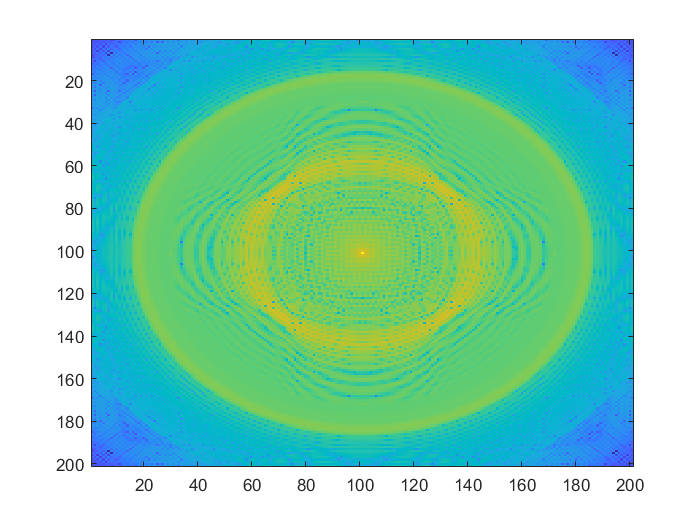

figure
imagesc(log(abs(fftshift(fft2(ifftshift(abs(U3+Ei).^2))))))

### 循环演示

% format long
% 
% n = 1;
% lambda = 680/10^9;
% kapa = 10;
% phi = 0;
% scale_factor = 1;
% M_size = 601;
% theta_spp = 90;
% theta_res = 47;
% [Ei,Es,~,I] = wave_generate(lambda*1e9,n,kapa,47,phi,scale_factor,M_size,theta_spp,theta_res);
% U1 = Es;
% F1 = fftshift(fft2(ifftshift(U1)));
% x = -300:300;
% k = 2*pi/lambda;
% fcut = 0.95*k/(2*pi);  % 空间截止频率 
% [X1,Y1] = meshgrid(x,x);
% fx1 = 10^7/M_size*X1;   % 物面横向频率
% fy1 = 10^7/M_size*Y1;   % 物面纵向频率
% 
% d10 = 2.5/1000;   % 物面是2.5mm
% d20 = 60*d10;  % 像面是60cm
% f = 1/(1/d10 + 1/d20);  % 焦距
% 
% figure
% for ii = -10:10
%     deltaz = ii*1e-6;  % 物面离焦距离
%     d1 = d10 + deltaz;  % 物面实际位置
%     d2 = d20;   % 像面实际位置
%     d0 = 1/(1/d1 + 1/d2 - 1/f); 
% 
%     X2 = lambda*d1*fx1; % 透镜面与物面相对应的空间横向坐标
%     Y2 = lambda*d1*fy1; % 透镜面与物面相对应的空间纵向坐标
%     P = sqrt(fx1.^2 + fy1.^2);  % 瞳函数
%     P(P<=fcut) = 1;
%     P(P>=fcut) = 0;
%     CTF0 = P.*exp(-i*k/2/d0*(X2.^2 + Y2.^2));  % 离焦瞳函数
%     CTF = conj(imrotate(CTF0,180));
%     F3 = CTF.*F1;
%     U3 = fftshift(ifft2(ifftshift(F3)));
%     imagesc(abs(U3+Ei).^2)
%     title(num2str(ii/10))
%     pause(0.2)
% end